# ISET3d: Materials

PBRT scene materials are stored in this slot **thisR.materials.   **A single material can be used to describe multiple objects in the scene. 

The slot is a struct that contains a number of useful entries.  The Simple Scene contains eight different materials.

The materials are stored as a Matlab 'map', which makes them easier to search through for large, complicated scenes.  Some of our scenes use a thousand different materials.

We read and write material properties using the usual set/get method

Setting material properties is essential for making realistic scenes.  We are constantly documenting and adding guides to specify materials with understandable names and properties. There was a substantial change in material properties in PBRT V4.0 so we are not likely to run out of tasks any time soon.

A material has many properties that define the object's color, surface roughness, specularity, and opacity. The color properties are separated in diffusion reflectance (kd), specular reflectance (ks), and mirror reflectance (kr).   We can specify the color in various ways, including RGB and spectral reflectance.

This tutorial illustrates how to set/get material properties and how to create new materials.

**See also**

  t_materials.m, piMaterialCreate, t_assets, t_piIntro*

## The base scene

This is the low resolution simple scene. We will introduce a set of material changes

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 7 materials.
Read 1 textures.
***Scene parsed.


thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5); 

piWrite(thisR);
scene = piRender(thisR, 'render type', 'radiance');

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/SimpleScene/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/
Pushed scene to remote in:   1.08
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt"
Successfuly rendered remotely in:   3.44
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/renderings/ /mnt/c/iset/iset3d-v4/local/SimpleScene/renderings
Retrieved output in:   1.12
Complete render took: 6.72e+00 seconds.*** Rendering time for SimpleScene:  6.7 sec ***

exr2bin done.

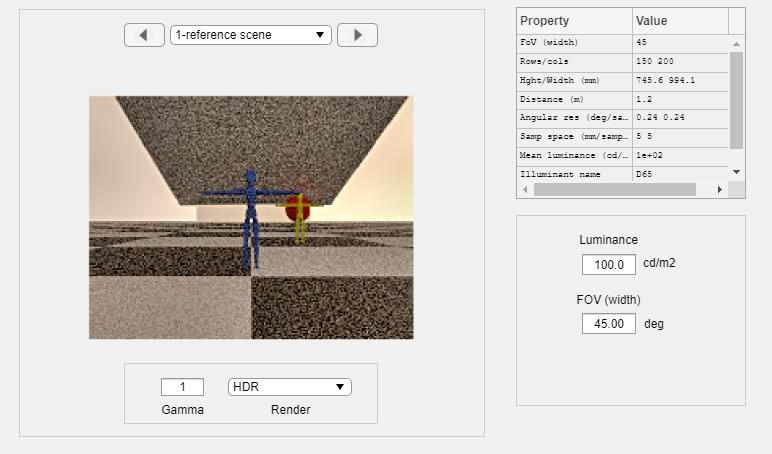

scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## List the scene materials

To list the materials in the scene, use this command

thisR.get('material print');


Scene materials: SimpleScene
-------------------------------
            name            type     
         ___________    _____________

    1    <undefined>    coateddiffuse
    2    BODY           diffuse      
    3    GLASS          dielectric   
    4    Material       coateddiffuse
    5    mirror         conductor    
    6    uber           coateddiffuse
    7    uber_blue      coateddiffuse

-------------------------------


## The material of an asset

Each asset (object node in the tree) has a material name.  We find the material for an object this way.

% The material of the blue stick figure
assetName = '001_figure_3m_O'; 
thisR.get('asset',assetName,'material name')

ans = 'uber_blue'

The material of the ceiling will become a mirror.  For now it is the black surface at the ceiling.

assetName = '001_mirror_O';
thisR.get('asset',assetName,'material name')

ans = 'mirror'

## Material properties

We get a material from its name.  We can also get just a specific property.

Find a material and print its properties

matName = 'uber_blue';
thisMat = thisR.get('material', matName)

thisMat = struct with fields:
              name: 'uber_blue'
      fluorescence: [1×1 struct]
     concentration: [1×1 struct]
              type: 'coateddiffuse'
       reflectance: [1×1 struct]
               eta: [1×1 struct]
         roughness: [1×1 struct]
        uroughness: [1×1 struct]
        vroughness: [1×1 struct]
    remaproughness: [1×1 struct]
          maxdepth: [1×1 struct]
          nsamples: [1×1 struct]
                 g: [1×1 struct]
            albedo: [1×1 struct]
         normalmap: [1×1 struct]
      displacement: [1×1 struct]
         thickness: [1×1 struct]


Check roughness

roughness = thisR.get('material', matName, 'roughness')

roughness = struct with fields:
     type: 'float'
    value: 0.5000


Check diffuse property

reflectance = thisR.get('material', matName, 'reflectance')

reflectance = struct with fields:
     type: 'rgb'
    value: [0.0477 0.1075 0.3424]


Check specular reflection property

%% need v4

Check mirror reflection property

%% need v4 kt = thisR.get('material', matName, 'kr')

Check property type (spectral, rgb)

kdType = thisR.get('material', matName, 'type')

kdType = 'coateddiffuse'

## Set material color: RGB format

The blue guy wants to be green today.

Change diffuse reflectance to be green

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/SimpleScene/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/
Pushed scene to remote in:   0.96
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt"
Successfuly rendered remotely in:   3.44
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/renderings/ /mnt/c/iset/iset3d-v4/local/SimpleScene/renderings
Retrieved output in:   1.11
Complete render took: 6.58e+00 seconds.*** Rendering time for SimpleScene:  6.6 sec ***

exr2bin done.

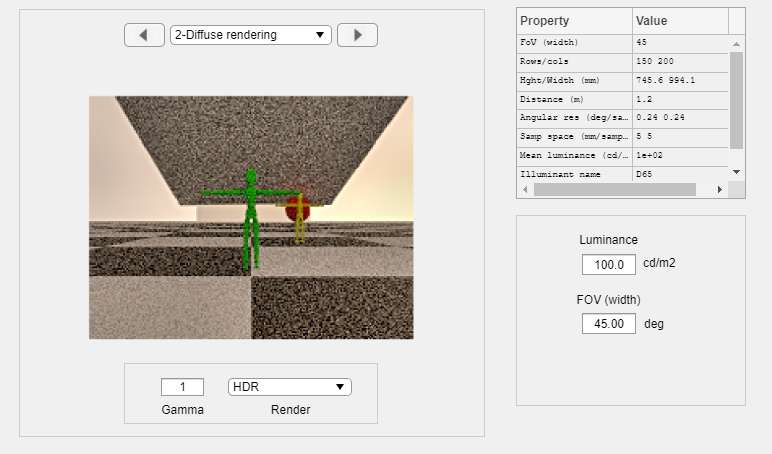

thisR.set('material', matName, 'reflectance', [0 0.5 0]);
piWRS(thisR,'name','Diffuse rendering','render type','radiance');

## Set material type: glass

The blue guy is feeling like glass, now.  So make a glass material.

glass = 'blueGuyGlass';
newMat = piMaterialCreate(glass, 'type', 'dielectric');
thisR.set('material', 'add', newMat);

Print the blue figure material and then change it to glass.

assetName = '001_figure_3m_O';
curName = thisR.get('asset', assetName, 'material name');
disp(['The current material is',curName]);

The current material isuber_blue


 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/SimpleScene/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/
Pushed scene to remote in:   0.96
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt"
Successfuly rendered remotely in:   3.47
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/renderings/ /mnt/c/iset/iset3d-v4/local/SimpleScene/renderings
Retrieved output in:   1.23
Complete render took: 6.76e+00 seconds.*** Rendering time for SimpleScene:  6.8 sec ***

exr2bin done.

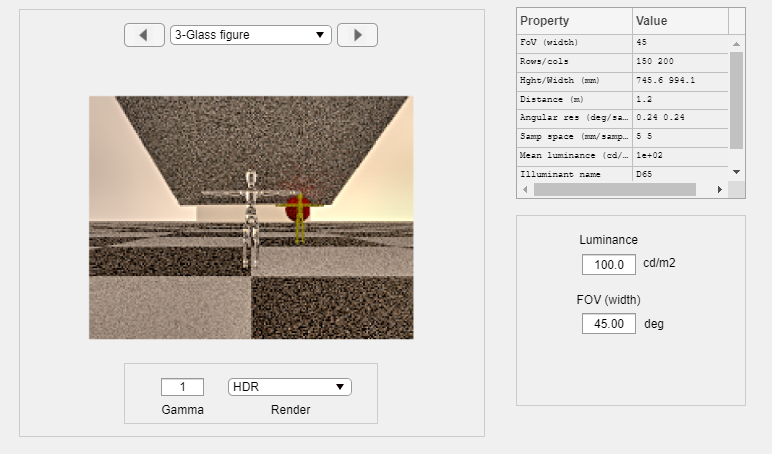

thisR.set('asset', assetName, 'material name', glass);
piWRS(thisR,'name','Glass figure','render type', 'radiance'); 

## Set material type: mirror

Create a mirror material

materialName = 'newMirror';
newMat = piMaterialCreate(materialName, 'type', 'conductor');
thisR.set('material', 'add', newMat);

This is the current black ceiling, and we change it to a mirror

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/SimpleScene/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/
Pushed scene to remote in:   1.19
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt"
Successfuly rendered remotely in:   3.77
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/renderings/ /mnt/c/iset/iset3d-v4/local/SimpleScene/renderings
Retrieved output in:   1.36
Complete render took: 7.65e+00 seconds.*** Rendering time for SimpleScene:  7.7 sec ***

exr2bin done.

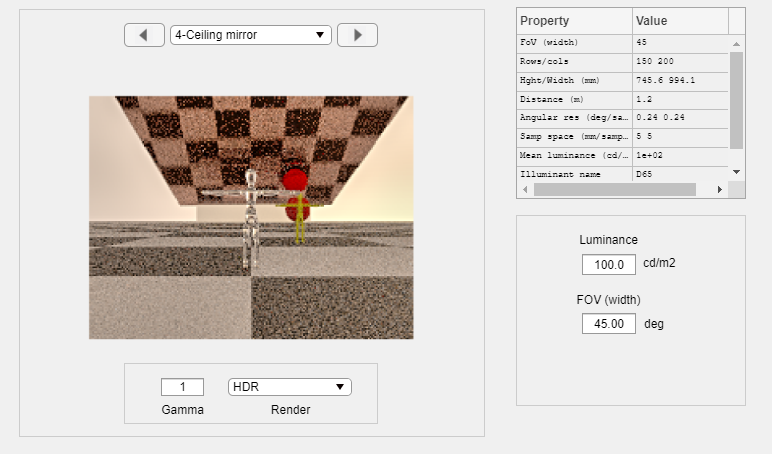

assetName = '001_mirror_O';
curName = thisR.get('asset', assetName, 'material name');
thisR.set('asset', assetName, 'material name', materialName);

piWRS(thisR,'name','Ceiling mirror','render type','radiance');

## Set material spectral reflectance

We can also specify the color using a spectral reflectance function

This is still the ceiling

assetName = '001_mirror_O';

Set the spectral reflectance of the matte material to the reflectance of the 10th chip in the MCC.  It is very red.

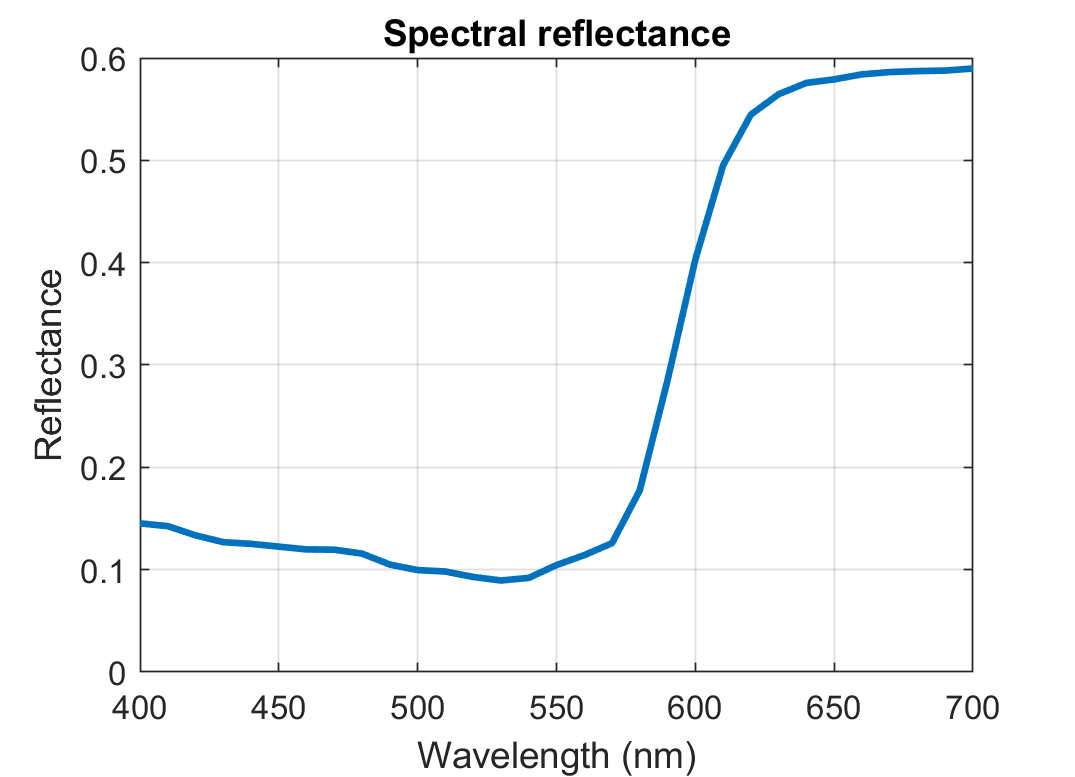

wave = 400:10:700;
mccRefs = ieReadSpectra('macbethChart', wave);
thisRef = mccRefs(:, 10);
ieNewGraphWin;
plotReflectance(wave,thisRef);

redName = 'newMatte';
redMaterial = piMaterialCreate(redName, 'type', 'diffuse');
thisR.set('material', 'add', redMaterial);

Convert the reflectance to the PBRT spd format.  It is (wave, value) ...

spdRef = piMaterialCreateSPD(wave, thisRef);

Store the spd reflectance as the diffuse reflectance of the newMatte material

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/SimpleScene/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/
Pushed scene to remote in:   1.31
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt"
Successfuly rendered remotely in:   3.89
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/SimpleScene/renderings/ /mnt/c/iset/iset3d-v4/local/SimpleScene/renderings
Retrieved output in:   1.24
Complete render took: 8.20e+00 seconds.*** Rendering time for SimpleScene:  8.2 sec ***

exr2bin done.

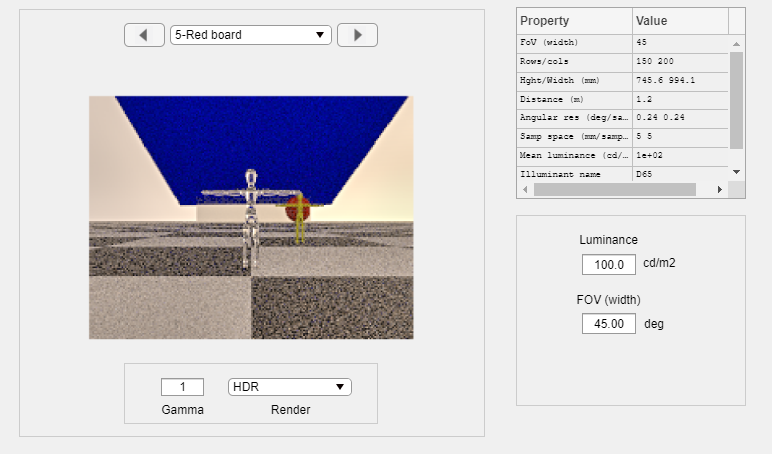

thisR.set('material', redName, 'reflectance', [0 0 1]);
thisR.set('asset', assetName, 'material name', redName);
piWRS(thisR,'name','Red board','render type','radiance');

% sceneSet(scene, 'render flag', 'hdr');

## Delete unused material

The blue guy never wants to be blue any more.

thisR.get('materials print');


Scene materials: SimpleScene
-------------------------------
              name            type     
          ____________    _____________

    1     <undefined>     coateddiffuse
    2     BODY            diffuse      
    3     GLASS           dielectric   
    4     Material        coateddiffuse
    5     blueGuyGlass    dielectric   
    6     mirror          conductor    
    7     newMatte        diffuse      
    8     newMirror       conductor    
    9     uber            coateddiffuse
    10    uber_blue       coateddiffuse

-------------------------------


Delete uber_blue material

deleteName = 'uber_blue';
thisR.set('material', 'delete', deleteName);

ans =   Map with properties:

        Count: 9
      KeyType: char
    ValueType: any


thisR.get('material print');


Scene materials: SimpleScene
-------------------------------
             name            type     
         ____________    _____________

    1    <undefined>     coateddiffuse
    2    BODY            diffuse      
    3    GLASS           dielectric   
    4    Material        coateddiffuse
    5    blueGuyGlass    dielectric   
    6    mirror          conductor    
    7    newMatte        diffuse      
    8    newMirror       conductor    
    9    uber            coateddiffuse

-------------------------------
